# Fahrplansimulation

% V5.2
tic
Import_timetable;  % Fahrplan wird eingelesen
Streckenparameter2;  % Strecken- und Fahrzeugparameter werden eingelesen
Import_track_ZLR_Data; % Strecken aus ZLR Daten werden importiert.
% Streckenparameter_parsing;

Fz_Nr = 1; % Initialisierung der Fahrzeugnummer

% erstellen einer Matrix, in welcher die Daten gespeichert werden.
sim_data = zeros(864000, length(Timetable.Start)+1);
sim_data(:,1) = 0.1:0.1:86400;
sim_dataBat = sim_data;

FZ = KISS; % Bestimmung des Fahrzeugtyps
% Str = ZH_HB; % Bestimmung der befahrenen Strecke
% Str = CH_StGallen_Wil;

% setting delay probability of each train (0.1 = 10% chance, 1 = 100% chance)
Delay = 0;

% laden der zuvor berechneten Batteriegrössen:
%load("BatterieAuslegung.mat")
CR = 10;

% loop über den gesamten Tag --> alle Fahrten auf den definierten Strecken werden simuliert
for t_start = 21480:32520 %28500:32520 %21480:21481  %57360:68700

    for i = 1:length(Timetable.Start)

        if (t_start == Timetable.Start(i))
            %disp(Timetable.Start(i))

            % Zufällige Verspätung generieren
            if(rand(1,1) < Delay)
                tDelay = (rand(1,1) * (1-0) + 0) * 60;
                Timetable.Start(i) = Timetable.Start(i) + tDelay;
            end
            
            Fahrtzeit = Timetable.Ende(i) - Timetable.Start(i);
            
            disp(Fahrtzeit)
                
            % Bestimmung der Strecke laut Fahrplan
            Str = Strecken.(string(Timetable.Strecke(i)));
            
            % Maximalgeschw. für die Einhaltung der Fahrtzeit wird berechnet
            Optimization4;

            %Str.speedLimits(:,2) = 75; %65.64;
            % Bestimmung des Fahrzeugtyps laut Fahrplan
%             FZ = Timetable.Fahrzeugtyp(i);

            % Aufruf der Funktion für die Simulation der Zugfahrt
            [Str_sim, Fz_sim, CompData] = Fahrtsimulation10(Str, FZ, const, OptimizationData);

            % aktueller Zeitpunkt festellen
            pos = find(sim_data(:, 1) == t_start);

            % Daten zum richtigen Zeitpunkt in die Matrix schreiben
            sim_data(pos:pos + length(Str_sim.Strecke) - 1, Fz_Nr + 1) = Fz_sim.Leistung;
            % Es kann angegeben werden, welcher Parameter ausgelesen werden soll.

            % Zeitpunkt an welchem Fahrzeug losfährt und ankommt
            time = seconds(transpose((Timetable.Start(i)):0.1:(Timetable.Start(i)-0.1+length(Str_sim.Strecke)/10)));
            time.Format = 'hh:mm:ss.S';
            CompData.time = time;
            Fz_Nr = Fz_Nr + 1;   % nächstes Fahrzeug
            StrName = "Fahrzeug" + i; % Name für Fahrzeug in Datenstruktur
            
            % Durchführung der Batterieauslegung:
            [BD] = AuslegungTraktionsBatterie(CR, CompData, const);
            BDTot.(StrName) = BD; 
                        
            % Erstellung einer Kopie der Simulation für die Berechnung mit
            % Batterieinput:
            CompDataBattery = CompData;
            CompDataBattery.Leistung = BD.("CR_10_Prozent").Psub;
            sim_dataBat(pos:pos + length(Str_sim.Strecke) - 1, Fz_Nr + 1) = BD.("CR_10_Prozent").Psub;

            % Zusammenfassung der gesamten Daten aller simulierten
            % Fahrzeuge
            CompleteData.(StrName) = CompData; % Simulierte Daten werden in Strucktur gespeichert
            CompleteDataBattery.(StrName) = CompDataBattery;

        end

    end

end

   120

   120

   180

   180

   120

   120

   180

   180

   180

   180

   120

   180

   120

   120

   180

   180

   240



Index exceeds the number of array elements. Index must not exceed 5.

Error in AuslegungTraktionsBatterie (line 117)
                EBatPeak(n) = EBatPeak(n) + sum(CompData.Leistung(xlin(i):xlin(i+1))-inters(n))*const.dt;


P_tot = sum(sim_data(:,2:end),2); % Gesamte Leistung aller Strecken wird berechnet
P_totBat = sum(sim_dataBat(:,2:end),2); % Gesamte Leistung Wenn Batterie eingesetzt wird.

toc

plot(CompData.Strecke, CompData.Beschleunigung)



## Analyse der Leistung

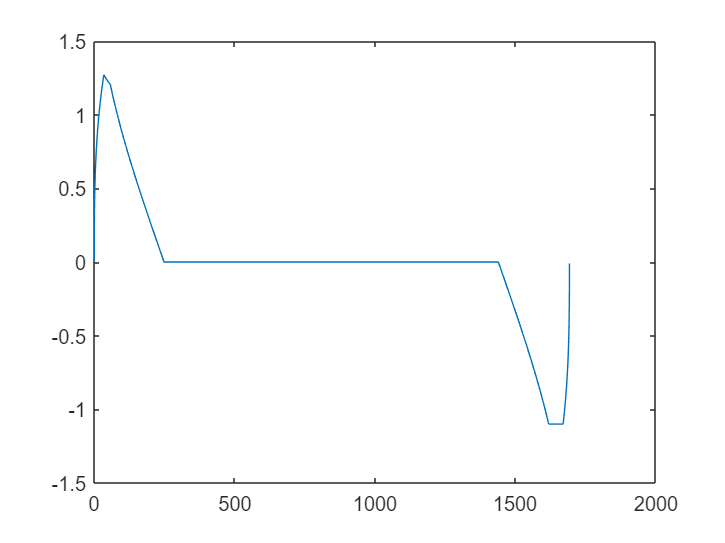

start = find((sim_data(1:end,2)),1,'first');
%start = pos;
finish = find((sim_data(1:end,Fz_Nr)),1,'last');

active = sim_data(start:finish, 1:end);
% 
time = seconds((active(1:end,1)));
time.Format = 'hh:mm:ss.S';

% plot(time, P_totPos(start:finish))
% grid()
% title('Leistungsverlauf der Fahrsimulation ohne negative Werte')
% xlabel('Zeit')
% ylabel('Leistung [MW]')
% plot(time, P_tot(start:finish,1)/1000, CompleteData.Fahrzeug1.time, CompleteData.Fahrzeug1.Leistung/1000, ...
%     CompleteData.Fahrzeug2.time, CompleteData.Fahrzeug2.Leistung/1000, ...
%     CompleteData.Fahrzeug5.time, CompleteData.Fahrzeug5.Leistung/1000)
hold on

plot(time, P_tot(start:finish,1)/1000)

Data inputs must match the axis configuration. A numeric axis must have numeric data inputs or data inputs which can be converted to double.

%plot(time, P_totBat(start:finish,1)/1000)
grid()
title('Leistung der Fahrtsimulation zwischen Stadelhofen - Zürich HB - Hardbrücke (morgens)')
xlabel('Zeit')
ylabel('Leistung [MW]')
legend(["Gesamtleistung" "Fahrzeug 1" "Fahrzeug 2" "Fahrzeug 5"])
hold off
% % 
% plot(time, active.Strecke)
% plot(time,P_tot(start:finish), time, sim_ZHHB(2,start:finish), time, sim_ZHHB(3, start:finish), time, sim_ZHHB(4, start:finish), time, sim_ZHHB(5, start:finish))
% grid()



## ZV-Diagram

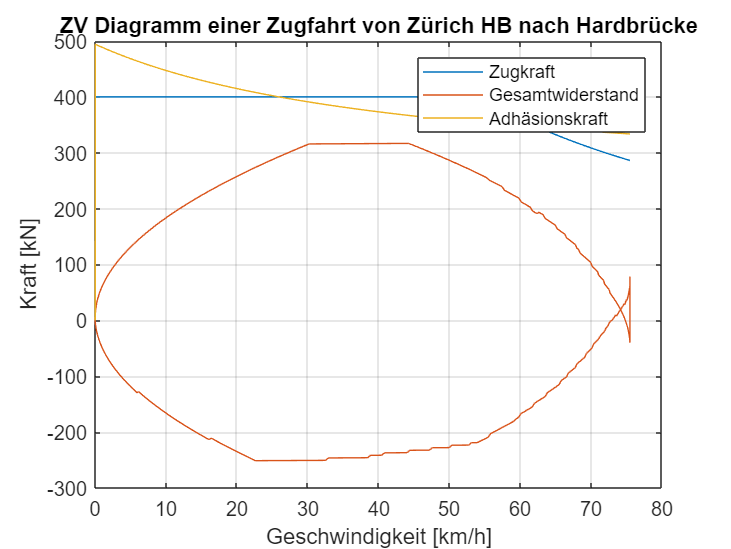

plot(CompleteData.Fahrzeug1.Geschwindigkeit, CompleteData.Fahrzeug1.Zugkraft, ...
    CompleteData.Fahrzeug1.Geschwindigkeit, CompleteData.Fahrzeug1.Gesamtwiderstand, ...
    CompleteData.Fahrzeug1.Geschwindigkeit, CompleteData.Fahrzeug1.("Adhäsionskraft"))
title('ZV Diagramm einer Zugfahrt von Zürich HB nach Hardbrücke')
xlabel('Geschwindigkeit [km/h]')
ylabel('Kraft [kN]')
legend(["Zugkraft" "Gesamtwiderstand" "Adhäsionskraft"])
grid()

## Plotten

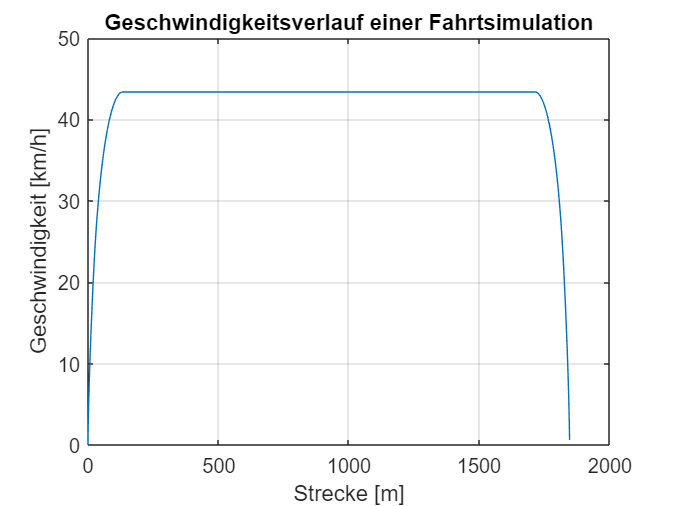


plot(Str_sim.Strecke, Fz_sim.Geschwindigkeit)
title('Geschwindigkeitsverlauf einer Fahrtsimulation')
xlabel('Strecke [m]')
ylabel('Geschwindigkeit [km/h]')
grid()

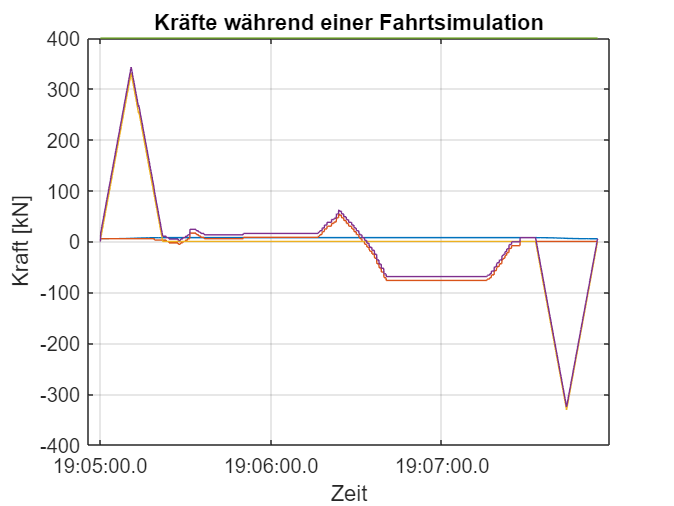


%plot(Str_sim.Strecke, Str_sim.Steigung)

% plot(sim_data.Zeit,sim_data.Geschwindigkeit)

% plot(CompData.time, Fz_sim.Beschleunigung, CompData.time, Str_sim.Strecke, CompData.time, Fz_sim.Geschwindigkeit)
% grid()
% title('Strecke, Geschwindigkeit und Beschleunigung')

plot(CompData.time, Fz_sim.Laufwiderstand, CompData.time, Fz_sim.Steigungswiderstand, CompData.time, Fz_sim.Beschleunigungswiderstand, CompData.time, Fz_sim.Gesamtwiderstand, CompData.time, Fz_sim.Zugkraft)
xlabel('Zeit')
ylabel('Kraft [kN]')
grid()
 
title('Kräfte während einer Fahrtsimulation')

## Plotten einer einzelnen Fahrt

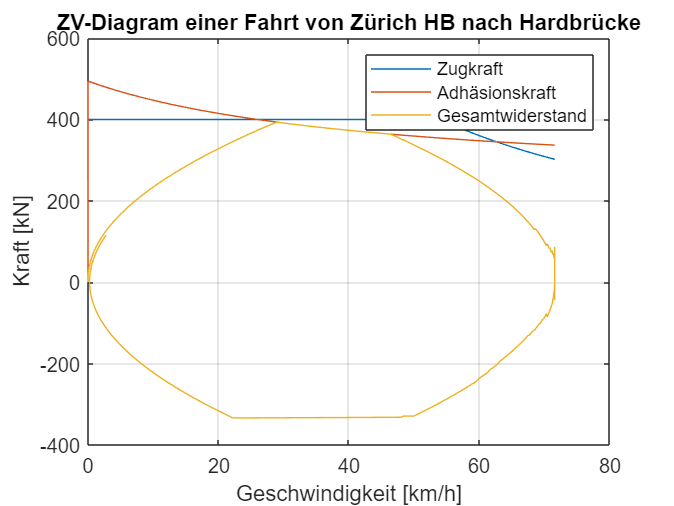

% Fahrt 2 von Zürich nach Hardbrücke:

% plot(CompleteData.Fahrzeug2.time, CompleteData.Fahrzeug2.Strecke)

plot(CompleteData.Fahrzeug2.Geschwindigkeit, CompleteData.Fahrzeug2.Zugkraft, CompleteData.Fahrzeug2.Geschwindigkeit, CompleteData.Fahrzeug2.("Adhäsionskraft"), CompleteData.Fahrzeug2.Geschwindigkeit,CompleteData.Fahrzeug2.Gesamtwiderstand)
grid()
xlabel('Geschwindigkeit [km/h]')
ylabel('Kraft [kN]')
legend(["Zugkraft" "Adhäsionskraft" "Gesamtwiderstand"])
title("ZV-Diagram einer Fahrt von Zürich HB nach Hardbrücke")

## 8 minütiger Mittelwert der Leistung

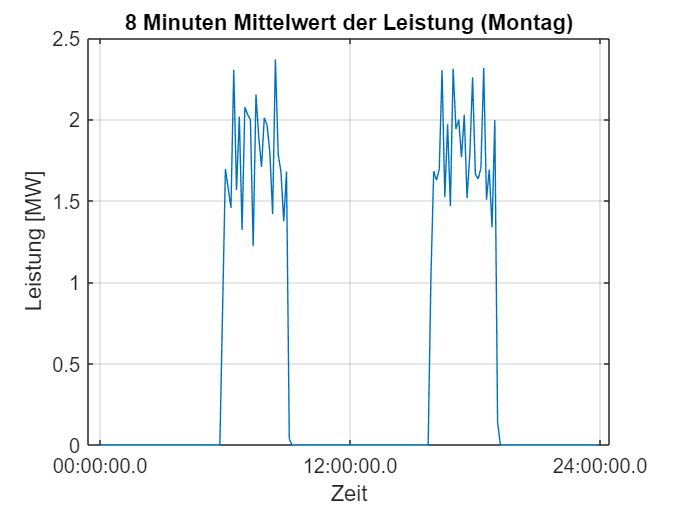

P_totPos = abs(P_tot);
P_tot8MinPos = mean(reshape(P_totPos,4800,[]))';
P_tot8MinPos(1,2) = 0;

P_tot8Min = (mean(reshape(P_tot,4800,[])))';
P_tot8Min(1,2) = 0;

for i = 2:180
    P_tot8MinPos(i, 2) = P_tot8MinPos(i-1,2) + 480;
end

for i = 2:180
    P_tot8Min(i, 2) = P_tot8Min(i-1,2) + 480;
end

time = seconds(P_tot8Min(:,2));
time.Format = 'hh:mm:ss.S';
plot(time, P_tot8Min(:,1)/1000)
title('8 Minuten Mittelwert der Leistung (Montag)')
xlabel('Zeit')
ylabel('Leistung [MW]')
grid()

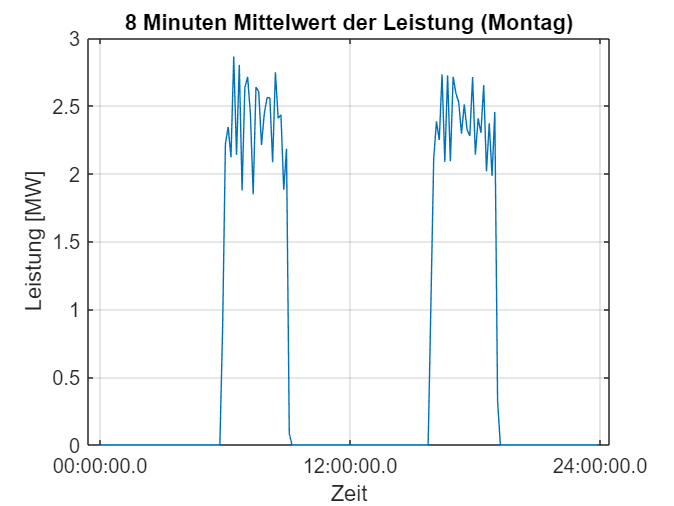


time = seconds(P_tot8MinPos(:,2));
time.Format = 'hh:mm:ss.S';
plot(time, P_tot8MinPos(:,1)/1000)
title('8 Minuten Mittelwert der Leistung (Montag)')
xlabel('Zeit')
ylabel('Leistung [MW]')
grid()


% P_tot8MinMonday = P_tot8Min;



## 8 Min Mittelwert alle 5 Minuten

P_totPos = (P_tot); % abs


n = 1;
for i = 1:3000:864000
    if (i <= 4800)
        
        P_tot8MinPos(1:4800,n)  = 0;
       
    else
        for k = 1:4800
            P_tot8MinPos(k ,n) = P_totPos(i-k);
        end
    end
    n = n + 1;
end

P_5to8MinMean = mean(P_tot8MinPos)';

P_5to8MinMean(:,2) = (1:length(P_5to8MinMean)) * 5;

time2 = minutes(P_5to8MinMean(:,2));
time2.Format = 'hh:mm:ss.S';

## plot Vergleich verschiedener 8 Min Werte

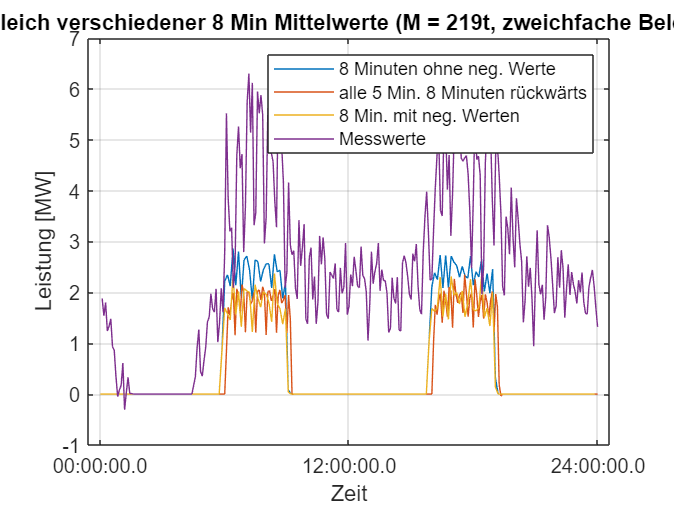

Import_measurements;
plot(time,P_tot8MinPos(:,1)/1000,time2, P_5to8MinMean(:,1)/1000, time, P_tot8Min(:,1)/1000, time2, MeasMonday.P8minMittelMW(2:end))
grid()  
title('Vergleich verschiedener 8 Min Mittelwerte (M = 219t, zweichfache Belegung)')
legend(["8 Minuten ohne neg. Werte" "alle 5 Min. 8 Minuten rückwärts" "8 Min. mit neg. Werten" "Messwerte"])
xlabel('Zeit')
ylabel('Leistung [MW]')

## Variablen für Montag:

P_5to8MinMeanMonday = P_5to8MinMean; % P_5to8MinMean = alle 5 Min. 8 Minuten rückwärts
P_totMonday = P_tot;
P_tot8MinMonday = P_tot8Min;
P_tot8MinPosMonday = P_tot8MinPos;
P_totPosMonday = P_totPos;

clearvars -except P_5to8MinMeanMonday P_totMonday P_tot8MinMonday P_tot8MinPosMonday P_totPosMonday

## Zwei Achsen

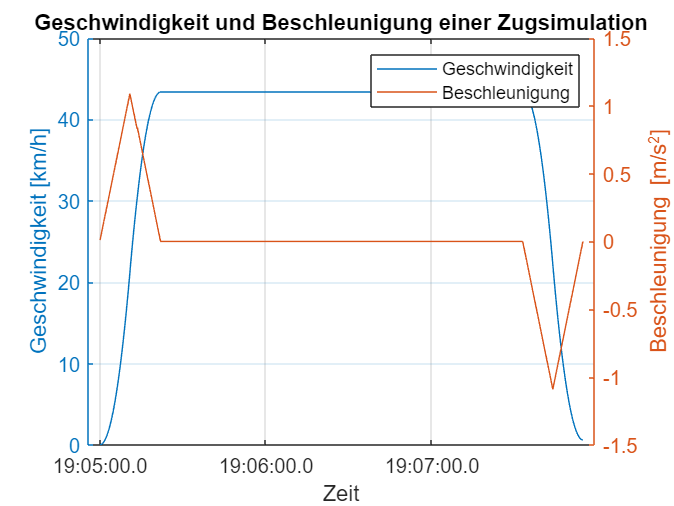

cla reset
yyaxis left
title('Geschwindigkeit und Beschleunigung einer Zugsimulation')
plot(CompData.time, Fz_sim.Geschwindigkeit)
xlabel('Zeit')
ylabel('Geschwindigkeit [km/h]')

yyaxis right
plot(CompData.time, Fz_sim.Beschleunigung)
ylabel('Beschleunigung [m/s^2]')
legend(["Geschwindigkeit" "Beschleunigung"])
grid()

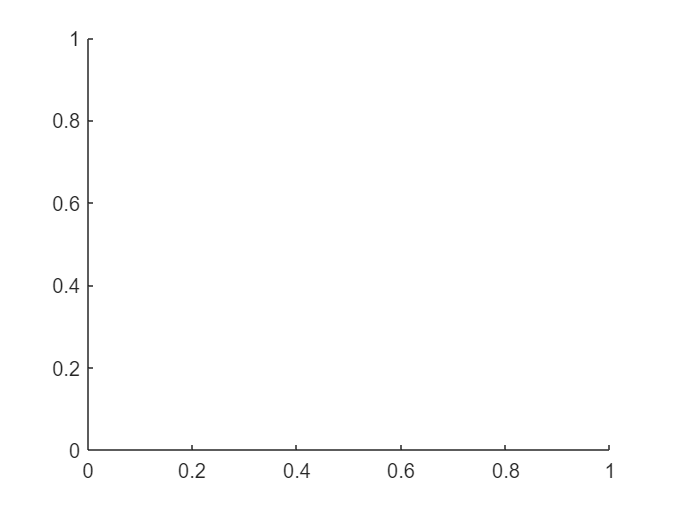


cla reset